# Import data from spreadsheet

Script for importing data from the following spreadsheet:

Auto-generated by MATLAB on 10-Aug-2024 11:59:43

## Set up the Import Options and import the data

opts = spreadsheetImportOptions("NumVariables", 12);

% Specify sheet and range
opts.Sheet = "heart";
opts.DataRange = "A2:L919";

% Specify column names and types
opts.VariableNames = ["Age", "Sex", "ChestPainType", "RestingBP", "Cholesterol", "FastingBS", "RestingECG", "MaxHR", "ExerciseAngina", "Oldpeak", "ST_Slope", "HeartDisease"];
opts.VariableTypes = ["double", "categorical", "categorical", "double", "double", "double", "categorical", "double", "categorical", "double", "categorical", "categorical"];

% Specify variable properties
opts = setvaropts(opts, ["Sex", "ChestPainType", "RestingECG", "ExerciseAngina", "ST_Slope", "HeartDisease"], "EmptyFieldRule", "auto");

% Import the data
heart = readtable("C:\Users\john\OneDrive\Documents\MATLAB\heart.xlsx", opts, "UseExcel", false)

heart = 918×12 table
    Age    Sex    ChestPainType    RestingBP    Cholesterol    FastingBS    RestingECG    MaxHR    ExerciseAngina    Oldpeak    ST_Slope    HeartDisease
    ___    ___    _____________    _________    ___________    _________    __________    _____    ______________    _______    ________    ____________

    40      M          ATA            140           289            0          Normal       172           N               0        Up             0      
    49      F          NAP            160           180            0          Normal       156           N     

### Clear temporary variables

clear opts

### Summary Statistics

We usually consider two types of summary statistics in EDA. That of a single variable and that of comparative summary statistics. In the former, we only consider a

single variable as a whole. In the latter, we divided the data set by the unique elements of a categorical variable and summarize another variable by each of the

groups formed by the classes of the categorical variable

#### Single variable summary statistics

The summary function summarizes each column in a table object (which contains the data in a spreadsheet which is in long-form tidy format).

% Summary statistics of all columns
summary(heart)

Variables:

    Age: 918×1 double

        Values:

            Min          28   
            Median       54   
            Max          77   

    Sex: 918×1 categorical

        Values:

            F      193   
            M      725   

    ChestPainType: 918×1 categorical

        Values:

            ASY      496   
            ATA      173   
            NAP      203   
            TA        46   

    RestingBP: 918×1 double

        Values:

            Min           0   
            Median      130   
            Max         200   

    Cholesterol: 918×1 double

        Values:

            Min           0   
            Median      223   
            Max         603   

    FastingBS: 918×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    RestingECG: 918×1 categorical

        Valu

% Create a variable of summary statistics
s_stats = summary(heart);
% Summary statistics of the Age column (variable)
s_stats.Age

ans = struct with fields:
           Size: [918 1]
           Type: 'double'
    Description: ''
          Units: ''
     Continuity: []
            Min: 28
         Median: 54
            Max: 77
     NumMissing: 0


% Summary statistics of Sex
s_stats.Sex

ans = struct with fields:
           Size: [918 1]
           Type: 'categorical'
    Description: ''
          Units: ''
     Continuity: []
     Categories: {2×1 cell}
         Counts: [2×1 double]
     NumMissing: 0


% Create a column vector of the Age variable
age = heart.Age;
% Mean of Age
mean(age)

ans = 53.5109

% Sample variance of Age (for a population variance use var(X,w=1))
var(age)

ans = 88.9743

% Sample standard deviation
std(age)

ans = 9.4326

% IQR
iqr(heart.Age)

ans = 13

% Frequency of classes in Sex variable
summary(heart.Sex)

     F      193 
     M      725 


#### Summary statistics by classes of a categorical type variable

As mention, we can also calculate comparative summary statistics. We start by using a MATLAB app and summarize the Age column by the two unique classes in

the Sex column. Be sure to name the analysis. Below, we use age_by_sex.

Use the Task button on the LIVE EDITOR tab.

% Compute group summary
age_by_sex = groupsummary(heart,"Sex",["mean","median","mode","max","min", ...
 "range","std","var","nummissing"],"Age")
% Create pivoted table
sex_chestpaintype = pivot(heart, Rows="Sex", Columns="ChestPainType", ...
 IncludeTotals=true, RowLabelPlacement="rownames")

#### Data visualization

The second important part of EDA is data visualization. We can also us a built-in app found in the Task button on the LIVE EDITOR tab to create plots.

**Single variable histogram**

We start with histogram of the Age column.

% Create histogram of heart.Age
hist_age = histogram(heart.Age,"DisplayName","Age");

#### Single variable box-and-whisker plot

Next we create a box-and-whisker plot of the RestingBP column. This variable measures the resting blood pressure in mm of mercury. Instead of an app, we use

code to create the plot.

% Create a box plot of the RestingBP variable
boxplot(heart.RestingBP,'Notch','on')
grid on
title("Distribution of the resting blood pressure values")
ylabel("Resting blood pressure [mm Hg]")
xticklabels({""})
hold off

#### Single variable bar chart

We saw in the previous chapter that bar plots are good for displaying the frequencies or relative frequencies of the classes of a categorical variable. We use the Sex

column below.

% Get frequencies of classes of Sex variable
summary(heart.Sex)

     F      193 
     M      725 


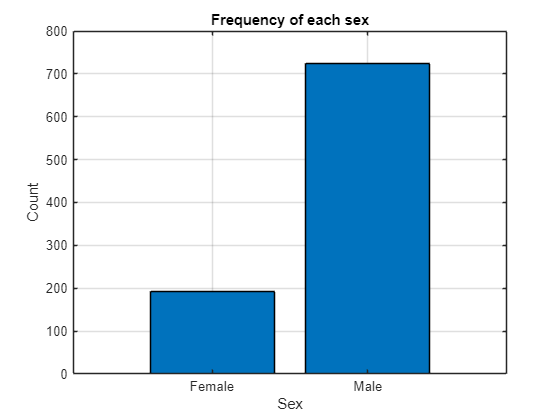


bar(["Female","Male"],[193,725])
grid on
title("Frequency of each sex")
xlabel("Sex")
ylabel("Count")
hold off

#### Scatter plot for two-numerical variables

A scatter plot visualizes the relationship between two numerical variables. We start with the Age and RestingBP column

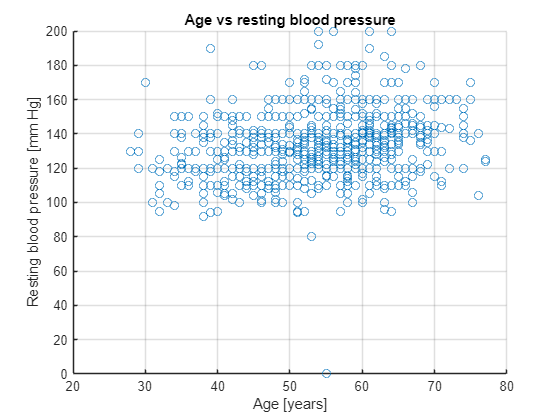

% Create a scatter plot of Age vs RestingBP
scatter(heart.Age,heart.RestingBP)
grid on
title("Age vs resting blood pressure")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

#### Scatter plot for two-numerical variables grouped by class

A scatter plot can also group the data by the unique elements of a categorical variable. Below we group the data by the two unique classes in the Sex column.

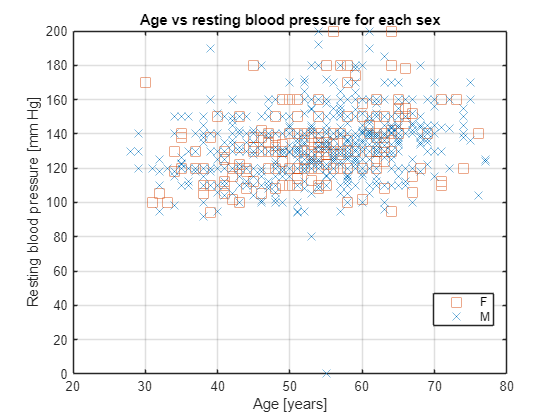

% Create a scatter plot of Age vs RestingBP for each class in Sex variable 
gscatter(heart.Age,heart.RestingBP,heart.Sex,[0.85 0.325 0.098; 0 0.447 0.741],'sx',[9 9])
grid on
title("Age vs resting blood pressure for each sex")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

#### Scatter plot of two-numerical variables including a third numerical variable

A scatter plot can also visualize a third numerical variable by considering color. Below we use the Cholesterol column.

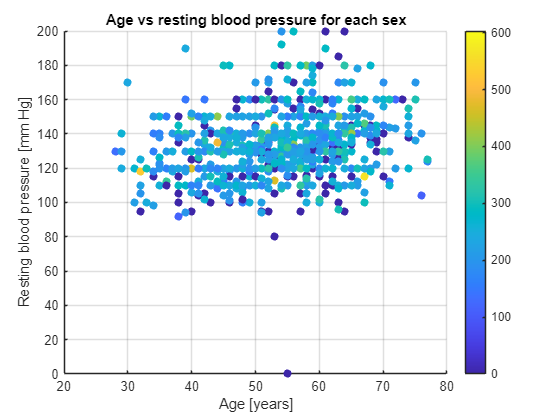

% Create a scatter plot of Age vs RestingBP and add the Cholesterol
% variable as numerical grouping column
scatter(heart,'Age','RestingBP','filled','ColorVariable','Cholesterol')
grid on
colorbar
title("Age vs resting blood pressure for each sex")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

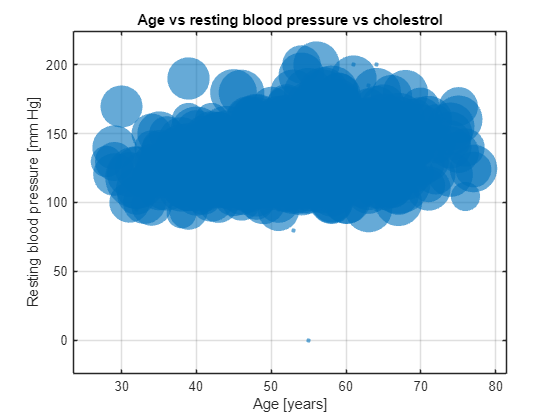

% A bubble chart can also display a third numerical variable, but uses size as an indicator of the value of the third variable
% Create a scatter plot of Age vs RestingBP and add the Cholesterol
% variable as numerical grouping column
bubblechart(heart,'Age','RestingBP','Cholesterol','MarkerEdgeColor','flat','MarkerEdgeAlpha',0.05)
grid on
title("Age vs resting blood pressure vs cholestrol")
xlabel("Age [years]")
ylabel("Resting blood pressure [mm Hg]")
hold off

#### Box-and-whisker plot grouped by classes

As final example, we group the Age values by the two classes in the Sex column to create a box-and-whisker plot.

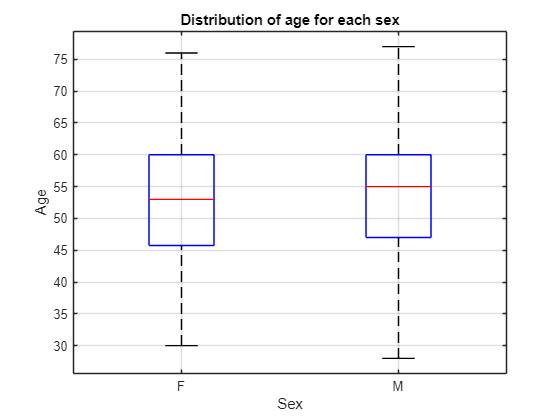

% Create a box plot of the Age variable for each of the classes in the Sex
% variable
boxplot(heart.Age,heart.Sex)
grid on
title("Distribution of age for each sex")
xlabel("Sex")
ylabel("Age")
hold off